% Magnetic Design
Vout=12;
Pout=60;
Vin_min=20;
Vin_max=40;
Iout=Pout/Vout;
efficiency_target=0.83;
Pin=Pout/efficiency_target;
fs=100*10^(3);

% Duty vs Turns Ratio
N_array=linspace(0.1,5,40);
voltage_gain_max=Vout/Vin_min;
voltage_gain_min=Vout/Vin_max;


dmax=voltage_gain_max./N_array./(1+voltage_gain_max./N_array);
dmin=voltage_gain_min./N_array./(1+voltage_gain_min./N_array);
figure
plot(N_array,dmax,"b")
hold on
plot(N_array,dmin,"r")
grid minor
xlabel("Turns Ratio")
ylabel("Duty Cycle")
title("Duty Cycle vs Turns Ratio")
N=0.5

N = 0.5000

Dmax=voltage_gain_max/N/(1+voltage_gain_max/N)

Dmax = 0.5455

Dmin=voltage_gain_min/N/(1+voltage_gain_min/N)

Dmin = 0.3750

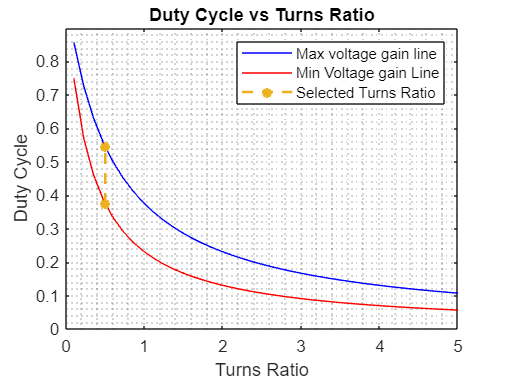

plot([N N],[Dmin Dmax],"--*","LineWidth",1.5)
legend("Max voltage gain line","Min Voltage gain Line","Selected Turns Ratio")

Selected turns ratio is 0.5. Dmax and Dmin are 0.545 and 0.375 respectively.

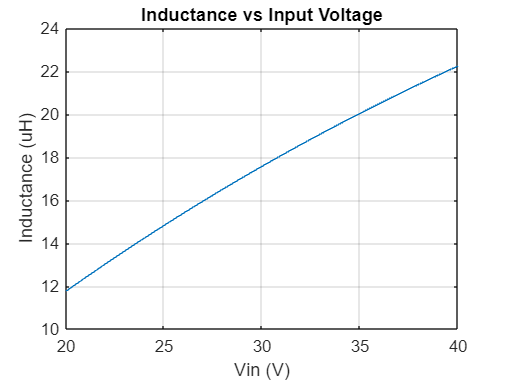

% Lm determination
Vin_array=linspace(Vin_min,Vin_max,50);
D_array = (Vout./(Vin_array*N))./(1+Vout./(Vin_array*N));
Iin_avg=Pin./Vin_array;
I_Lm_avg=Iin_avg./D_array;
Krf_DCM_boundary=0.7; %ripple factor
delta_I_Lm_array=I_Lm_avg*Krf_DCM_boundary*2;
Lm_array=(Vin_array.*D_array).^2/(fs*2*Pin*Krf_DCM_boundary)*10^6;
figure
plot(Vin_array,Lm_array)
grid on
title("Inductance vs Input Voltage")
ylabel("Inductance (uH)")
xlabel("Vin (V)")

Lm=30*10^-6

Lm = 3.0000e-05

Krf_peak_current_boundary=0.35;
Lm_max=(Vin_min.*Dmax).^2/(fs*2*Pin*Krf_peak_current_boundary)*10^6;

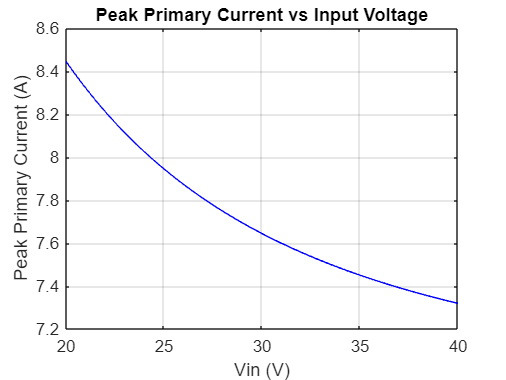

delta_I_Lm_array=Vin_array.*D_array/(Lm*fs);
Krf_array=delta_I_Lm_array./(2*I_Lm_avg);
I_Lm_peak_array=I_Lm_avg+delta_I_Lm_array/2;
figure
plot(Vin_array,I_Lm_peak_array,"b")
grid on
title("Peak Primary Current vs Input Voltage")
ylabel("Peak Primary Current (A)")
xlabel("Vin (V)")

I_Lm_peak=max(I_Lm_peak_array);

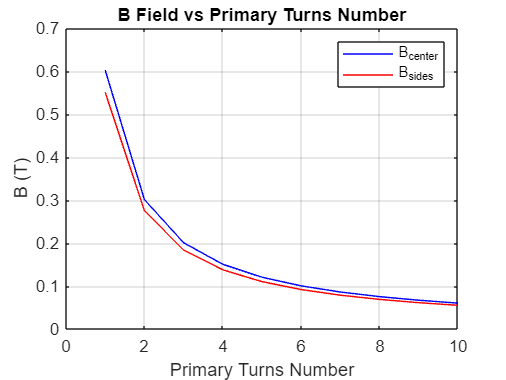

% Deciding Turns Number 
% Core 0P45530EC

% Permeability of air
mu0 = 4*pi*1e-7;

% Define core parameters
A = 56.2e-3;
B = 27.6e-3;
C = 24.61e-3;
D = 18.5e-3;
E = 37.5e-3;
F = 17.10e-3;
L = 9.35e-3;
M = 10.15e-3;

% Core area
Ae=420e-6; 
Asides=L*C;
Acenter=F*C;
Awindow=M*D*2;

primary_turns_array=linspace(0,10,11);
reluctance_array=primary_turns_array.^2/Lm;
phi_peak_array=(primary_turns_array*I_Lm_peak)./reluctance_array;
B_sides_array=phi_peak_array/(2*Asides);
B_center_array=phi_peak_array/Acenter;
figure
plot(primary_turns_array,B_center_array,"b")
hold on
plot(primary_turns_array,B_sides_array,"r")
grid on
title("B Field vs Primary Turns Number")
ylabel("B (T)")
xlabel("Primary Turns Number")
legend("B_center","B_sides")

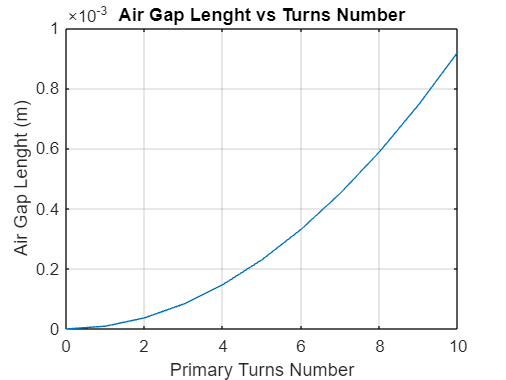


gap_lenght_array=reluctance_array*(2*mu0*Acenter*Asides)/(2*Asides+Acenter);
figure
plot(primary_turns_array,gap_lenght_array)
grid on
title("Air Gap Lenght vs Turns Number")
ylabel("Air Gap Lenght (m)")
xlabel("Primary Turns Number")

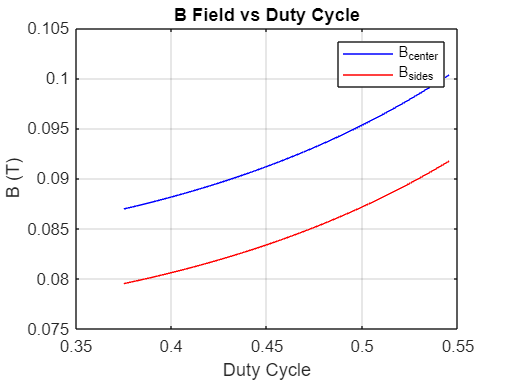

N1=6;
N2=N1*N;
R_gap=N1^2/Lm;
l_gap=R_gap*(2*mu0*Acenter*Asides)/(2*Asides+Acenter);
phi_array=(N1*I_Lm_peak_array)./R_gap;
B_sides_array=phi_array/(2*Asides);
B_center_array=phi_array/Acenter;
plot(D_array,B_center_array,"b")
hold on
plot(D_array,B_sides_array,"r")
grid on
title("B Field vs Duty Cycle")
ylabel("B (T)")
xlabel("Duty Cycle")
legend("B_center","B_sides")


phi_peak=(N1*I_Lm_peak)./R_gap;
B_sides_peak=phi_peak/(2*Asides)

B_sides_peak = 0.0917

B_center_peak=phi_peak/Acenter

B_center_peak = 0.1003

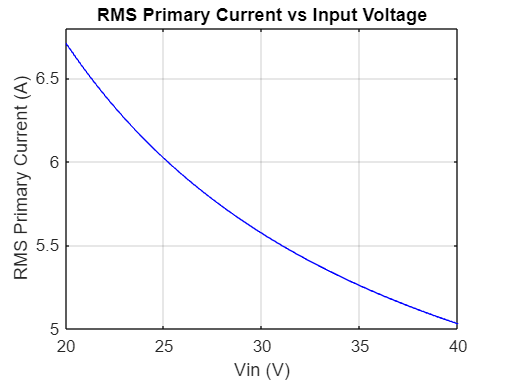

% Current Calculation
delta_I_primary_max=max(delta_I_Lm_array);
I_primary_rms_array=sqrt((I_Lm_avg).^2+(delta_I_Lm_array/(2*sqrt(3))).^2);
figure
plot(Vin_array,I_primary_rms_array,"b")
title("RMS Primary Current vs Input Voltage")
ylabel("RMS Primary Current (A)")
xlabel("Vin (V)")
grid on

I_primary_rms_max=max(I_primary_rms_array);
I_secondary_rms_max=I_primary_rms_max/N;

% AWG Cable Selection
cu_resistivity=1.724e-8;
skin_depth=sqrt(cu_resistivity/(pi*fs*mu0*1));
strand_section=pi*skin_depth^2*1e6; % 0.1372 mm^2 AWG27-26
AWG26_area=0.129; %mm^2
AWG26_current_carry_capacity=0.361; %A
safety_factor=0.75; % Since the wire is wounded capacity is decreased


primary_parallel=ceil(I_primary_rms_max/(AWG26_current_carry_capacity*safety_factor));
secondary_parallel=ceil(I_secondary_rms_max/(AWG26_current_carry_capacity*safety_factor));
primary_total_cable=primary_parallel*N1;
secondary_total_cable=secondary_parallel*N2;
total_cable=secondary_total_cable+primary_total_cable;
cable_area=total_cable*AWG26_area*1e-6;
fill_factor=cable_area/Awindow

fill_factor = 0.1030


% fill factor is quite small instead of changing the core lets use 2nd
% secondary winding
total_cable_2sec=secondary_total_cable*2+primary_total_cable;
cable_area_2sec=total_cable_2sec*AWG26_area*1e-6;
fill_factor_2sec=cable_area_2sec/Awindow

fill_factor_2sec = 0.1546

% Copper Loss Calculation
%% MLT calculation
confidence_percentage=1.1;
MLT=(F+C)*2*confidence_percentage;
length_primary=MLT*N1;
length_secondary=MLT*N2;

AWG26_cable_resistance=0.1338568; %ohm/m
primary_resistance= AWG26_cable_resistance*length_primary/primary_parallel;
secondary_resistance=AWG26_cable_resistance*length_secondary/secondary_parallel;

primary_copper_loss=I_primary_rms_max^2*primary_resistance;
secondary_copper_loss=I_secondary_rms_max^2*secondary_resistance;
total_copper_loss=primary_copper_loss+secondary_copper_loss % Watt

total_copper_loss = 0.2654

% Core Loss Calculation 
%% Steinmetz coefficients given by Magnetics is applied for P type ferrite core


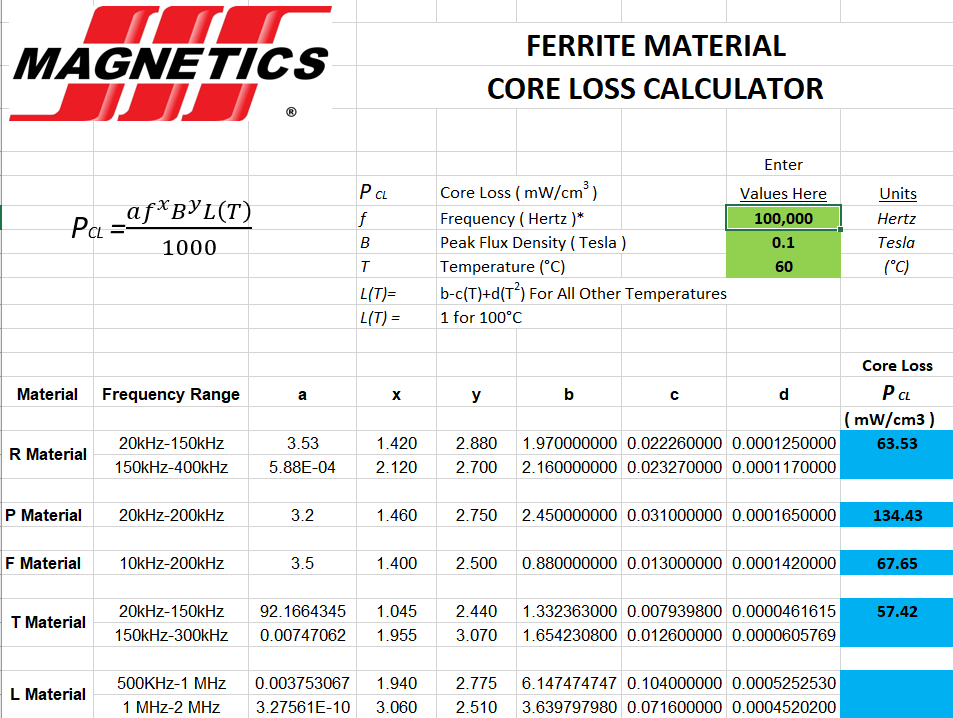

a=3.53;
x=1.420;
y=2.880;
b=1.97;
c=0.02226;
d=0.000125;
T=60;
LT=b-c*T+d*(T)^2;
Pcl=a*fs^(x)*B_center_peak^(y)*LT/1000; %mW/cm^3
Vcore=52000/1000*2; %cm^3
P_core=Pcl*Vcore/1000 % W

P_core = 6.6706